% Clear existing variables from workspace
clearvars

% Import some of the package classes
import Inputs.*
import Solvers.*
import Solvers.Mixture.*

% InputSet is used to create a collection of input settings
inputSet = InputSet( ...
    modelFilePath = './inputs/models.inp', modelID = 'BARCS', ...
    optionsFilePath = './inputs/options.inp', optionsID = 'STEADY', ...
    geometryFilePath = './inputs/geom.inp', geometryID = 'BARC', ...
    bcFilePath = './inputs/bc_barc_sinePower.inp', ...
    sessionParentDir = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE = 'BOTH');


% Create a mixture solver
mixSolver = MixtureSolver(inputSet);

% mixSolver is initialized at construction. 
% Here, it is explicitly initialized for clarity.
mixSolver.initializeSolver();

% Solve (does not accept any argument)
mixSolver.solve();



--------------------------------------------- Mixture solver run initiated ---------------------------------------------

Run steady-state ...
Time  1.00 [s]	max point iter =   5 in node  12, max errors: W = 0.0000007 [kg/s], P = 9.72544 [Pa], H = 0.99896 [J/kg]
Time  2.00 [s]	max point iter =   4 in node  13, max errors: W = 0.0000103 [kg/s], P = 6.57949 [Pa], H = 0.99457 [J/kg]
Time  3.00 [s]	max point iter =   3 in node   9, max errors: W = 0.0000010 [kg/s], P = 0.53321 [Pa], H = 0.11259 [J/kg]
Time  4.00 [s]	max point iter =   3 in node  14, max errors: W = 0.0000021 [kg/s], P = 8.79790 [Pa], H = 0.40257 [J/kg]
Time  5.00 [s]	max point iter =   3 in node  28, max errors: W = 0.0000002 [kg/s], P = 9.89159 [Pa], H = 0.72124 [J/kg]
Time  6.00 [s]	max point iter =   3 in node  57, max errors: W = 0.0000003 [kg/s], P = 9.94641 [Pa], H = 0.71706 [J/kg]
Time  7.00 [s]	max point iter =   2 in node  17, max errors: W = 0.0000004 [kg/s], P = 4.87564 [Pa], H = 0.84430 [J/kg]
Time  8.00 [s]	

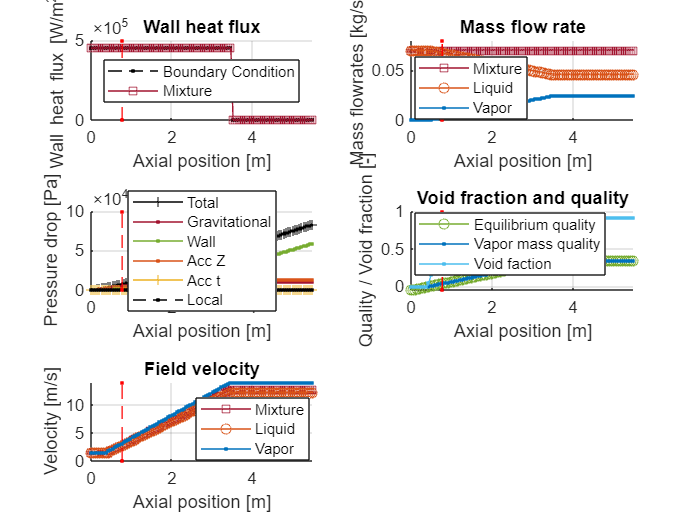


% Axial and temporal plots
plotter = mixSolver.plotz(1); % Axial plot at 1st time step

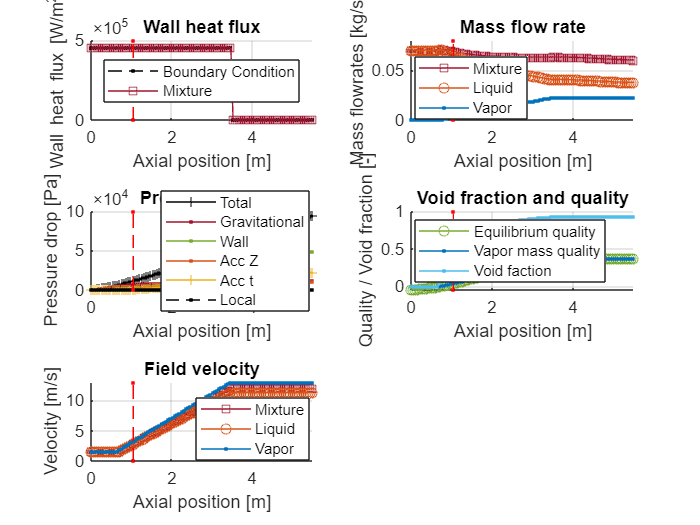

mixSolver.plotz(mixSolver.NTIME); % Axial plot at final time step

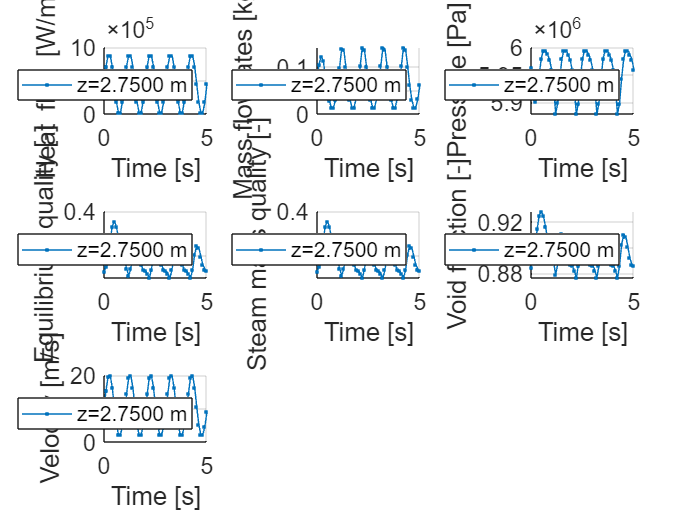


mixSolver.plott(round(mixSolver.NZ/2)); % Temporal plot at mid point

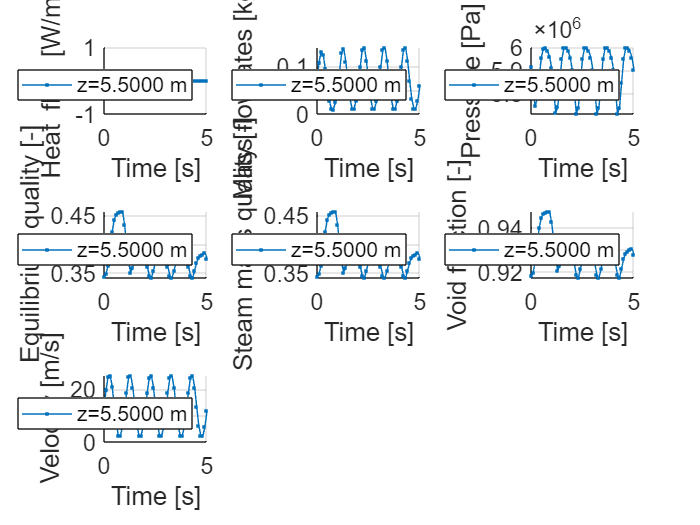


mixSolver.plott(mixSolver.NZ); % Temporal plot at last spatial␣node

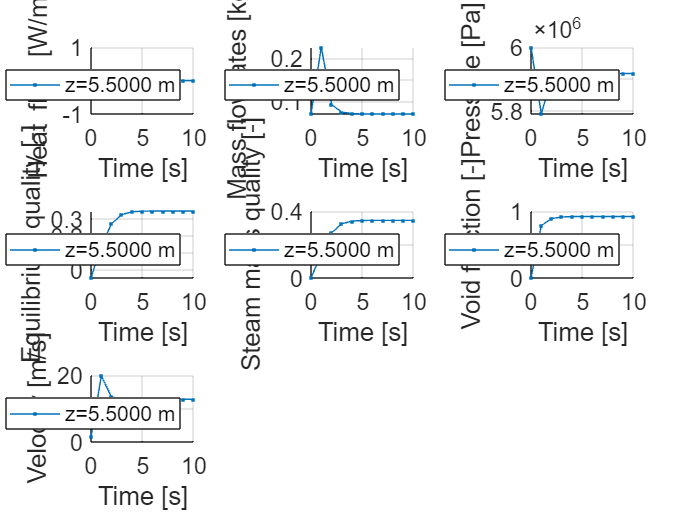


mixSolver.plott(mixSolver.NZ,'solveMode','STEADY'); % Temporal plot at last spatial␣node of 

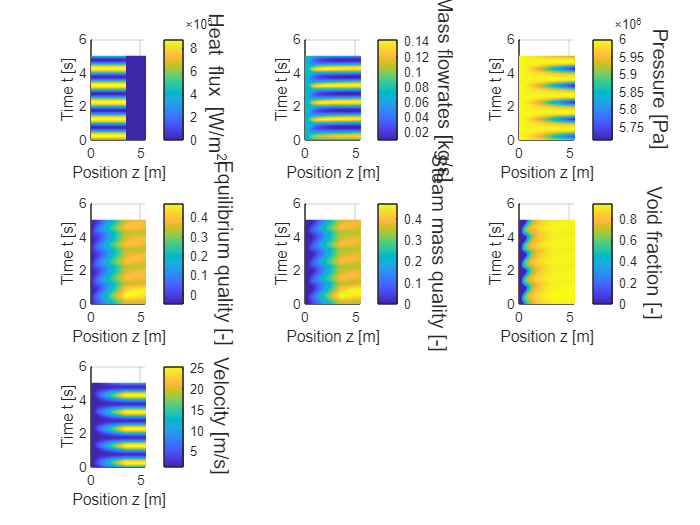

                                                   % steady state solution
mixSolver.plotzt(mixSolver.NZ,"solveMode","TRANSIENT"); % Spatial-temporal map of transient solution at channel exit


% Save results
mixSolver.saveResults(saveFormat="MAT");
